folder = "DB1"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
for i = 1:nfiles
  filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
  %subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
  Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
  %imshow(Im{i}) %%Show the current image in a subplot.
end

Convert to YCbCr and create an eye map according to the *Face Detection in Color Images* paper.

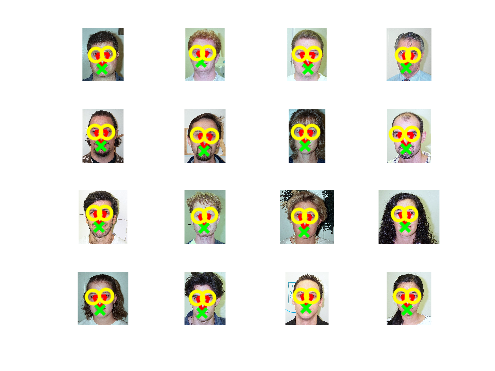

%The following requires image processing toolbox.
tic
figure;
for i = 1:length(Im)
    subplot(4,4, i); %%define location to plot the image in our subplot.
    currentImage = Im{i};
    currentImage = lighting_compensation(currentImage,0.20);
    
    EyeMap = eye_detection(currentImage);
    size_img = size(currentImage);
    %EyeMap = bwpropfilt(EyeMap, 'Perimeter', 7);
    MouthMap = mouth_detection(currentImage);
    
    [lEye_c, rEye_c, mouth_c, e_regions,m_regions ] = face_triangle_coordinates(MouthMap, EyeMap);
    
    imshow(currentImage)
    hold on
%     plot([1,size_img(2)],[3/5*size_img(1),3/5*size_img(1)],'Color','b','LineWidth',2)
%     plot([1,size_img(2)],[2/5*size_img(1),2/5*size_img(1)],'Color','b','LineWidth',2)
%     plot([1,size_img(2)],[3.9/5*size_img(1),3.9/5*size_img(1)],'Color','b','LineWidth',2)
    plot([lEye_c(1),rEye_c(1)],[lEye_c(2),rEye_c(2)],'Color','r','LineWidth',2)
    plot([mouth_c(1),rEye_c(1)],[mouth_c(2),rEye_c(2)],'Color','r','LineWidth',2)
    plot([mouth_c(1),lEye_c(1)],[mouth_c(2),lEye_c(2)],'Color','r','LineWidth',2)
    for idx = 1:length(m_regions)
        plot(m_regions(idx).Centroid(1),m_regions(idx).Centroid(2), 'x', 'markersize', 8, "LineWidth",2, 'Color', 'green')
    
    end
    for idx = 1:length(e_regions)
        plot(e_regions(idx).Centroid(1),e_regions(idx).Centroid(2), 'o', 'markersize', 8, "LineWidth",2, 'Color', 'yellow')
    
    end
    hold off
end 

toc

Elapsed time is 12.140421 seconds.


tic
allFaces = cell(1,nfiles); %%Allocate space

for j = 1:length(Im)
    currentImage = Im{j};
    currentImage = lighting_compensation(currentImage,0.20);
    EyeMap = eye_detection(currentImage);
    MouthMap = mouth_detection(currentImage);
    
    [lEye_c, rEye_c, mouth_c, e_regions,m_regions ] = face_triangle_coordinates(MouthMap, EyeMap);
    [rotated_image, lEye_rotated, rEye_rotated, mouth_rotated] = rotate_image(currentImage, lEye_c, rEye_c, mouth_c);
    
%     figure;
%     subplot(1,2,1);
%     imshow(rotated_image);
%     hold on
%     plot([lEye_rotated(1),rEye_rotated(1)],[lEye_rotated(2),rEye_rotated(2)],'Color','r','LineWidth',2)
%     plot([mouth_rotated(1),rEye_rotated(1)],[mouth_rotated(2),rEye_rotated(2)],'Color','r','LineWidth',2)
%     plot([mouth_rotated(1),lEye_rotated(1)],[mouth_rotated(2),lEye_rotated(2)],'Color','r','LineWidth',2)
%     hold off
    
    cropped_image = crop_face(rotated_image, lEye_rotated, rEye_rotated);
%    subplot(1,2,2);
%    imshow(cropped_image);
    allFaces{j} = cropped_image;
end

toc

Elapsed time is 17.675268 seconds.


Calculate eigenfaces.

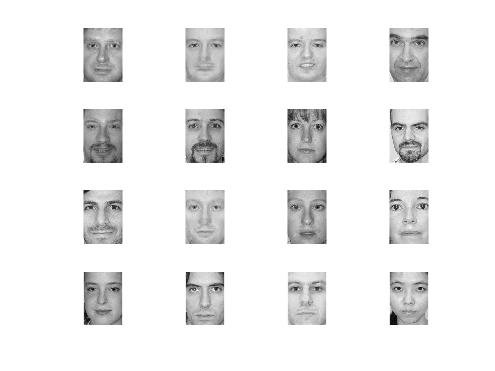

[linearCombination, weight, averageFace, u, index]= compute_eigenFace(allFaces);
figure;
for i = 1:16
    subplot(4,4,i);
    imshow(linearCombination{i});
end

Check if image is in database. Should be moved to a function

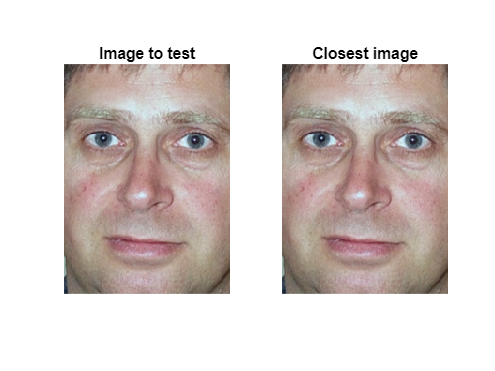

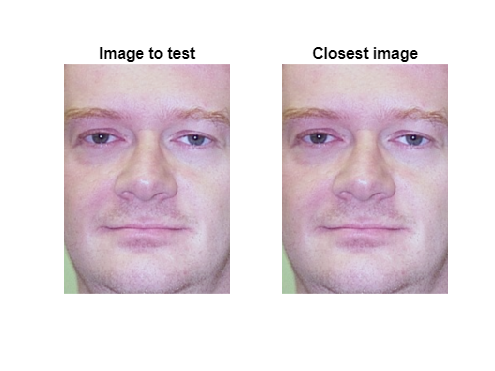

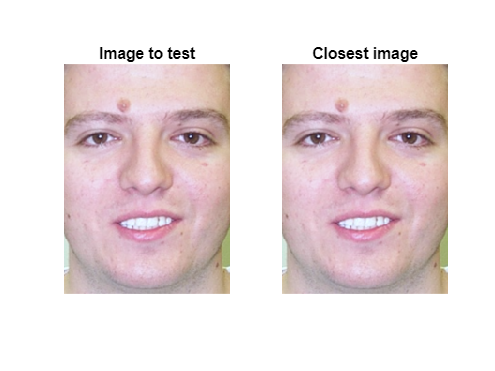

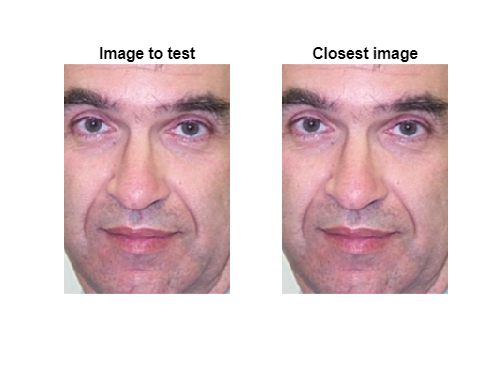

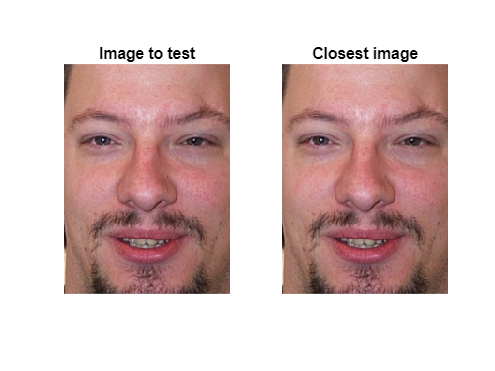

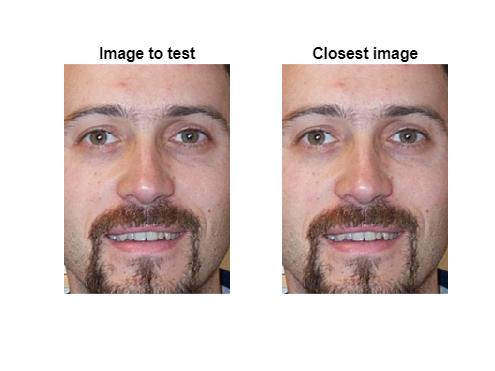

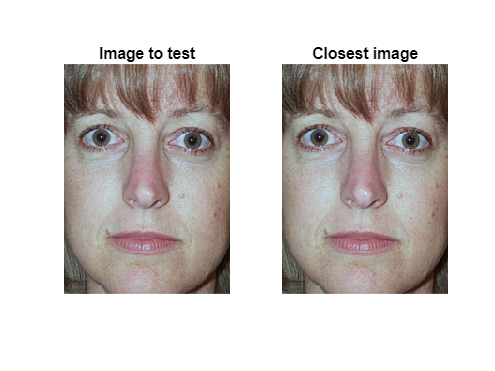

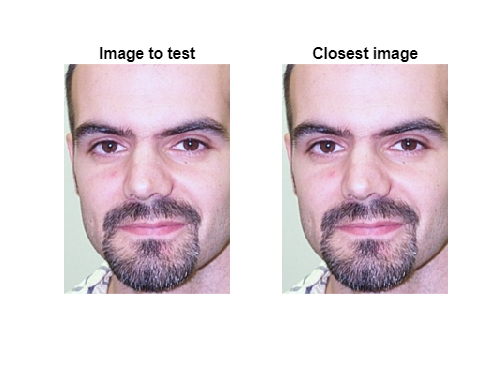

for k = 1:16
    testFace = allFaces{k};
    figure;
    subplot(1,2,1);
    imshow(testFace);
    title('Image to test');
    
    %%Reshape the test image and subtract the average face.
    testFace = rgb2gray(testFace);
    testFace = reshape(testFace,[],1);
    phi = testFace - averageFace;
    
    %%Calculate weights
    weight2 = zeros(1,12);
    for j = 1:12
        weight2(1,j) = u(:,index(j))'* phi;
    end
    
    error = 10000; %%minimum error
    index2 = 0;
    
    for i = 1:16
        if sqrt(sum((weight2 - weight(i,:)).^2)) < error
            error = sqrt(sum((weight2 - weight(i,:)).^2)); %%update minimum error
            index2 = i; %%update index.
        end
    end
    
    subplot(1,2,2);
    imshow(allFaces{index2});
    title('Closest image');
end